# Laboratorio 3

Para que el programa corra se necesita que los archivos "One.fis" y "Two.fis" esten en la carpeta actual de trabajo:

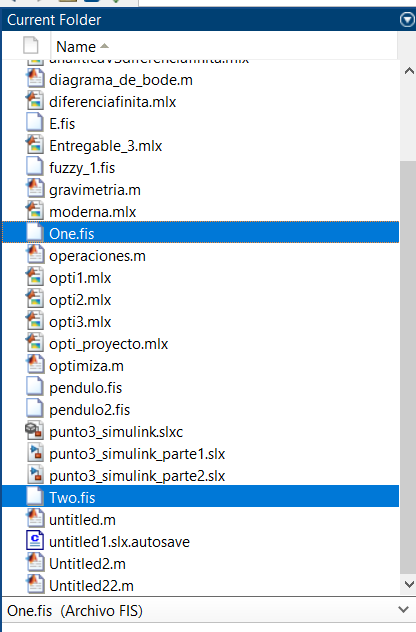

**1. **Sintetice los puntos principales de la consulta realizada sobre los modos de disposición de los controles difusos.

**Respuesta:**

Es fundamental entender la necesidad de implementar la lógica difusa para controlar sistemas con un grado de aleatoriedad y alteraciones externas. Es esencial usar una herramienta que permita que el sistema reaccione adecuadamente a estas condiciones. Los sistemas de lógica difusa se emplean para resolver problemas relacionados con las incertidumbres del sistema, los cambios ambientales y la información incompleta. El uso de la lógica difusa no solo satisface estas necesidades, sino que también permite que el sistema sea autoajustable. Por esta razón, la lógica difusa se implementa en la inteligencia artificial y otras aplicaciones.

Para comprender qué es la lógica difusa, debemos partir del concepto de conjuntos difusos, que son conjuntos en los que la pertenencia de los elementos no es absoluta. En un conjunto difuso, cada elemento tiene un grado de pertenencia representado por un valor que oscila entre 0 y 1. Este concepto se puede expresar mediante la ecuación 1.

Expresión del conjunto difuso

Adicionalmente, se definen los elementos que pertenecen a dicho conjunto. Estos elementos pueden tener valores entre 0 y 1, indicando el grado de pertenencia al conjunto:

Aquí se define el valor del elemento y su pertenencia dentro de un conjunto.

Para ilustrar mejor esta relación, se presenta un gráfico que muestra un conjunto difuso y sus elementos representados.

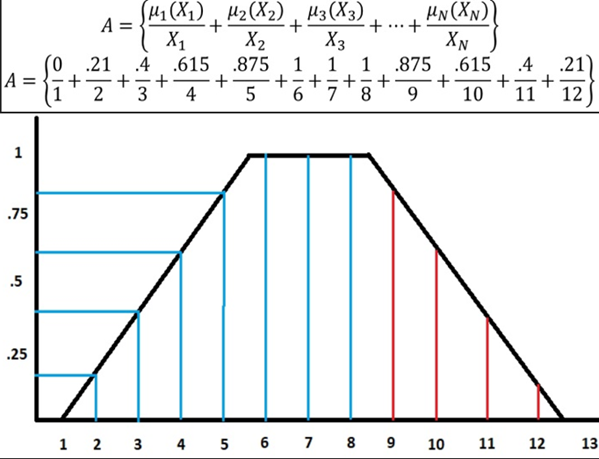

Figura 1. Representación de conjunto difuso

Entendido qué es un elemento y un conjunto difuso, es importante considerar las funciones de pertenencia. Estas funciones describen el comportamiento de los datos según su ubicación en el conjunto, proporcionando una idea clara de cómo funciona el sistema, lo cual es crucial para el control. Las funciones de pertenencia pueden tener diferentes formas, como funciones triangulares, trapezoidales o gaussianas, cada una con características específicas que se ajustan a diferentes tipos de problemas.

Las proposiciones difusas constituyen la información ajustada en el sistema por el usuario. En la figura 2 se muestran los distintos tipos de funciones de pertenencia.

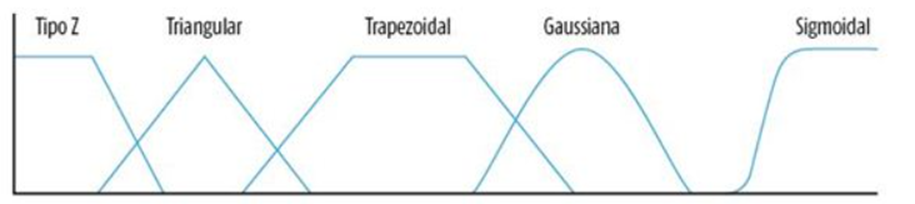

Figura 2. Tipos de funciones de pertenencia

El siguiente paso para implementar la lógica difusa es iniciar la etapa del mecanismo de inferencia. Aquí se definen las reglas y cómo van a interactuar. Recordando que estamos hablando de conjuntos difusos, estos tendrán reglas de unión, intersección y complemento. Estas reglas permiten combinar y modificar los grados de pertenencia de los elementos según las condiciones del sistema. En la figura 3 se muestra la aplicación gráfica de estas interacciones.

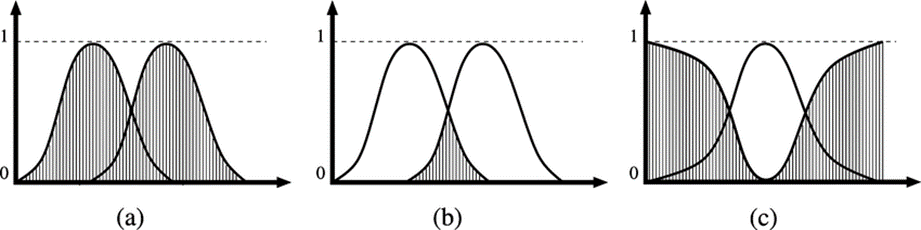

Figura 3. Operaciones difusas: (a) unión, (b) intersección y (c) complemento.

Las operaciones entre conjuntos difusos se definen mediante un producto cartesiano, que es una operación matemática fundamental para combinar los conjuntos difusos y obtener nuevos conjuntos a partir de los existentes.

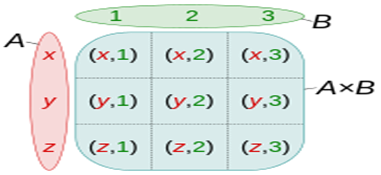

Figura 4. Producto cartesiano difuso

Este producto se representa en la tabla 1, que muestra el conjunto de relaciones surgidas por la inferencia. La inferencia difusa utiliza estas relaciones para deducir nuevas informaciones basadas en las reglas definidas previamente.

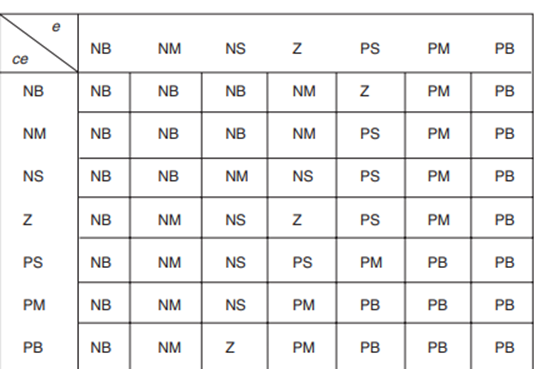

Tabla 1. Relaciones difusas

Finalmente, con esta información se puede entender cómo funciona la lógica difusa. En la figura 5 se aprecia el proceso completo: primero, la fuzzificación, donde se asignan los valores de acuerdo al universo deseado y se ubican los elementos según las funciones de pertenencia; luego, la implementación de las reglas de inferencia y la base de datos, asignando los valores de pertenencia a cada dato. De acuerdo con las relaciones entre conjuntos, se obtienen los valores deseados y se desdifusifica para que el sistema pueda interpretar la información.

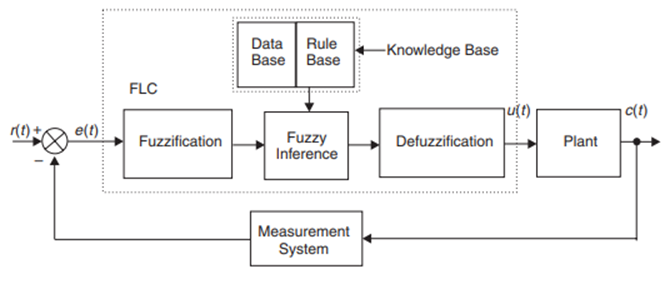

Figura 5. Control por lógica difusa

La desdifusificación es la última etapa. Se obtiene el conjunto resultante de la inferencia, como se muestra en la figura 6. Se busca el centroide, que corresponde al valor real. Esto se calcula con la siguiente expresión, que indica la sumatoria de los datos del conjunto final difuso sobre los valores reales, permitiendo obtener el valor no difuso. La desdifusificación convierte el resultado difuso en una cantidad precisa que puede ser utilizada por el sistema controlado.

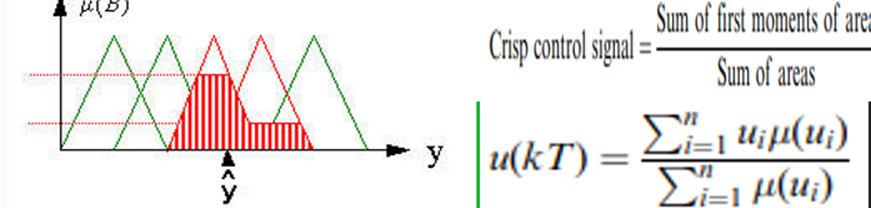

Figura 6. Desdifusificación y expresión

El siguiente nivel en el control difuso corresponde a los sistemas autoorganizados. Estos sistemas incluyen una etapa adicional que permite ajustar las reglas de manera constante y automática, mejorando así la adaptabilidad y la eficiencia del sistema de control. En la figura 7 se puede apreciar el esquema de este tipo de control.

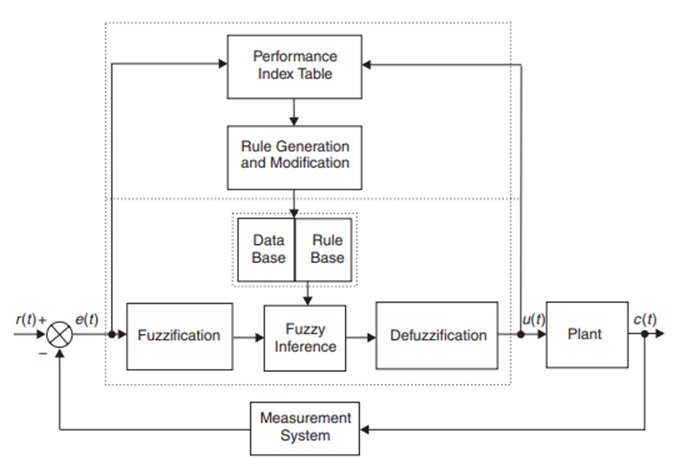

Figura 7. Esquema de control difuso autoorganizado

Los sistemas autoorganizados difusos se basan en la capacidad de aprendizaje y adaptación. Incorporan mecanismos que evalúan el rendimiento del sistema y ajustan las reglas de inferencia y las funciones de pertenencia en respuesta a cambios en el entorno o en el propio sistema. Este proceso puede implicar el uso de algoritmos de optimización, como algoritmos genéticos, redes neuronales o técnicas de retroalimentación, para refinar continuamente las reglas y mejorar el control.

**2. **Sintetice y documente el desarrollo logrado del ejemplo plasmado en el documento “2_Fuzzy Logic example”, reportando en el archivo de Live Script su ejecución y enviando los códigos generados para su alcance.

**Respuesta:**

One = readfis('one'); 
X1 = evalfis(One,2437.4)        %Valor de voltaje que compensa las entradas

X1 = 2.3746

Se observa un valor cercano al ejemplo considerando que los limites de las funciones fueron tomadas por observcion de las graficas.

Two = readfis('Two');
X2 = evalfis(Two, [65 -0.1])        %Valor del fuerza que compensa las entradas

X2 = 0.3295

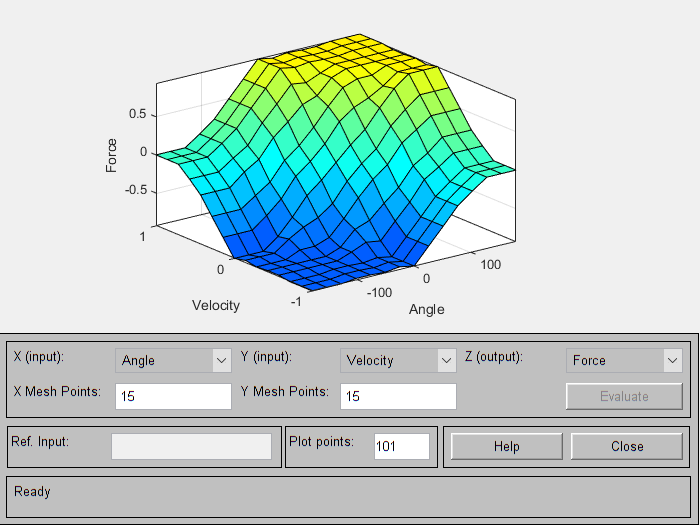

surfview(Two)

Se observa nuevamente un valor cercano al obtenido en el ejemplo, cabe recalcar que los intervalos de los estados se asumieron arbitrariamente equidistantes segun la grafica mostrada en la figura 11 del documento "*1_Fuzzy Logic Example*"

**3.** Sintetice y documente el desarrollo logrado del ejemplo plasmado en el libro “Advanced Control Engineering”, reportando en el archivo de Live Script su ejecución y enviando los códigos generados para su alcance.

**Respuesta:**

El ejemplo 10.3 del libro trata del diseño de un controlador lógico difuso para un sistema de péndulo invertido. El objetivo es que el péndulo se mantenga en la posición vertical.

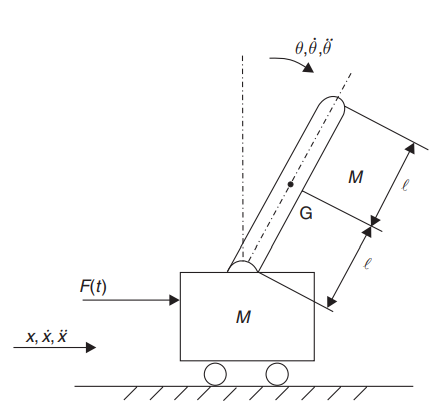

Para modelar el sistema utiliza loas ecuaciones de de movimiento de Johnson y Picton.

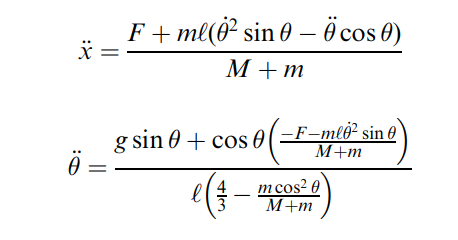

La primera describe la aceleración horizontal del carro que sostiene el péndulo. Esta expresión está en términos de  la fuerza centrífuga debido al movimiento del péndulo y la componente horizontal de la aceleración angular del péndulo.

La segunda ecuación describe cómo las fuerzas gravitacionales y las fuerzas resultantes del movimiento del carro afectan la aceleración angular del péndulo

Si asumimos que theta es pequeño podemos linealizar las ecuaciones y nos queda lo siguiente:

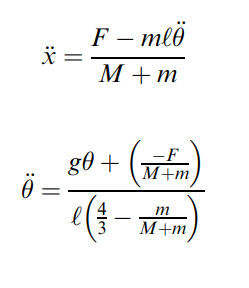

Ahora lo pasamos a espacio de estados. Para ello primero llamamos las variables de estado.

Y la estrada es:

Finalmente se construye la ecuación de estado.

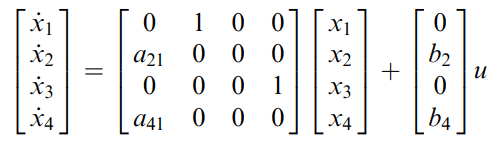

Donde

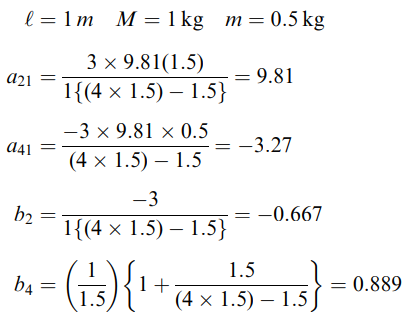

Y la salida es:

Luego se diseña un controlador K buscando unos polos ideales, los cuales son:

La ecuación característica quedaría:

Y con la ecuación de Ackerman la matrix de estado retroalimentado queda como:

Luego se usa un enfoque de lógica difusa sugerido por Johnson y Picton el cual es:

- **Cuatro ventanas de entrada:** con tres conjuntos (uno para cada variable de estado) y una ventana de salida con tres conjuntos

- **Reglas heurísticas:** derivadas de experimentos de equilibrio de escoba para construir una base de reglas tipo Mamdani.

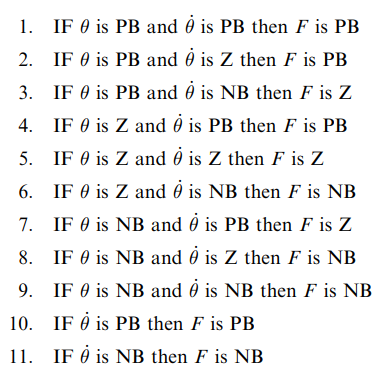

Finalmente se crean los diagramas para cada variable de estado y para la salida.

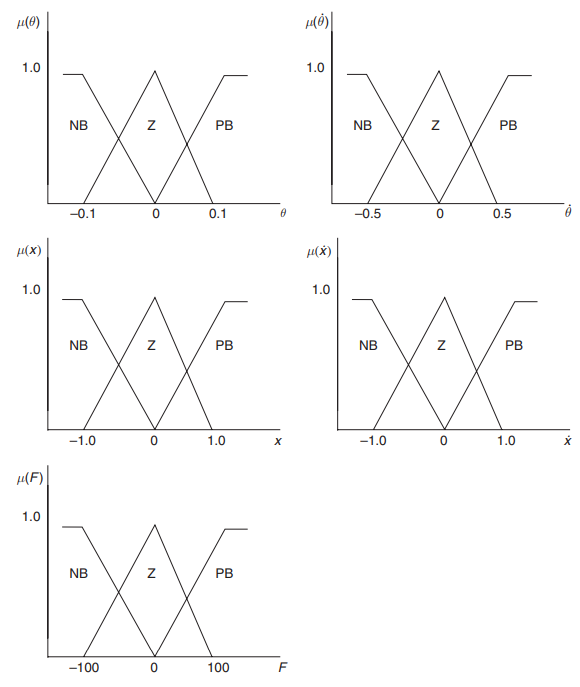

Codigo:

%Regulator design using pole placement
% Inverted pendulum problem
A = [0 1 0 0; 9.81 0 0 0; 0 0 0 1; -3.27 0 0 0];
B = [0; -0.667; 0; 0.889];
C = [1 0 0 0; 0 1 0 0; 0 0 1 0; 0 0 0 1];
D = zeros(4,1);
%Rango
rank_of_M=rank(ctrb(A,B))

rank_of_M = 4

%Enter desired characteristic equation 
chareqn=[1 12 72 192 256];
%Calculate desired closed-loop poles 
desiredpoles=roots(chareqn)

desiredpoles =   -4.0000 + 4.0000i
  -4.0000 - 4.0000i
  -2.0000 + 2.0000i
  -2.0000 - 2.0000i


%Calculate feedback gain matrix using Ackermann's formula 
K=acker(A, B, desiredpoles)

K =  -174.8258  -57.1201  -39.1437  -29.3578


theta=174;
tdot=57.1;
x=39.1;
xdot=29.3;
%Nueva función de transferencia
A_new = A - B * K;
sys_new = ss(A_new, B, C, D)

sys_new =
 
  A = 
           x1      x2      x3      x4
   x1       0       1       0       0
   x2  -106.8   -38.1  -26.11  -19.58
   x3       0       0       0       1
   x4   152.2   50.78    34.8    26.1
 
  B = 
           u1
   x1       0
   x2  -0.667
   x3       0
   x4   0.889
 
  C = 
       x1  x2  x3  x4
   y1   1   0   0   0
   y2   0   1   0   0
   y3   0   0   1   0
   y4   0   0   0   1
 
  D = 
       u1
   y1   0
   y2   0
   y3   0
   y4   0
 
Continuous-time state-space model.


step(sys_new)

Respuesta usando ubicación de polos.

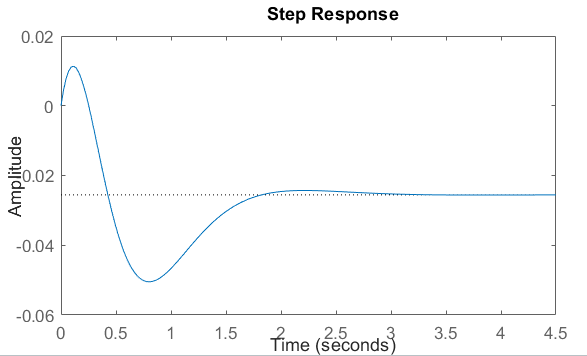

Respuesta con Fuzzy 11 condiciones

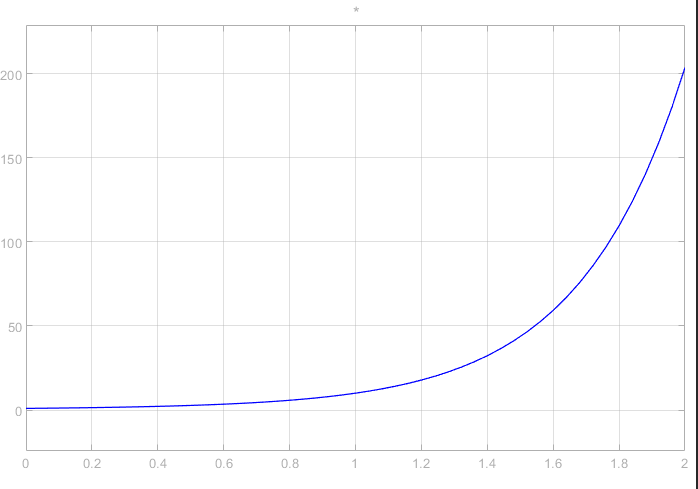

Respuesta con fuzzy 22 condiciones

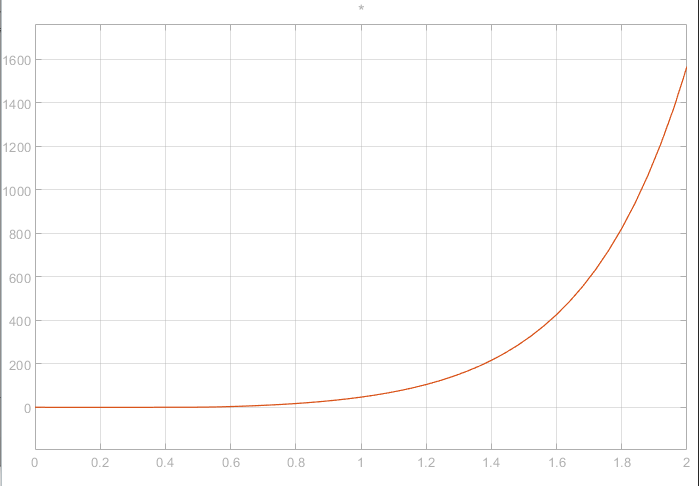

Con respecto a la grafica siguiente:

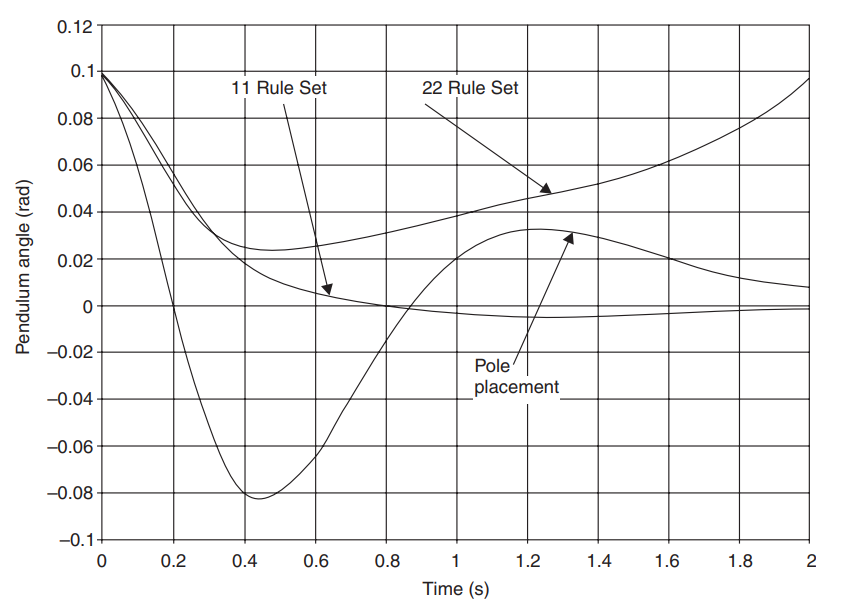

**4.** Sintetice y documente el desarrollo logrado montaje generado del control para la planta de nivel bajo la propuesta del artículo “4_Paper Fuzzy” “Case 3”, reportando en el archivo de Live Script su ejecución y enviando los códigos generados para su alcance.

**Respuesta:**

El articulo en general habla de el uso de la teoría de conjuntos difusos en el control de sistemas difíciles de modelar, destacando la aceptación generalizada de los controladores lógicos difusos (FLCs) como una solución prometedora para problemas no lineales.

Se menciona la preferencia por los FLCs sobre los controladores lineales PID convencionales debido a su mayor robustez y menor sensibilidad a variaciones paramétricas. Además, se discute la importancia de seleccionar el tipo de controlador adecuado según la aplicación, señalando que los FLCs tipo PID son comunes y prácticos, con los PI-FLCs y PD-FLCs como los más utilizados.

En el "Caso 3"  se aborda el control de un sistema lineal inestable de segundo orden con tiempo muerto, conocido como "Planta B" en el artículo. Este tipo de sistema presenta desafíos adicionales en el diseño de controladores debido a su inestabilidad inherente y la presencia de tiempo muerto.

Se utilizan los siguientes controladores:

- **C-PID Controller**: Se diseñan las ganancias del controlador proporcional, integral y derivativo convencional para este sistema inestable. En el caso 3 las constantes son sacados con Z-N.

- **NA-PID-FLC**: l controlador NA-PID-FLC (Non-Adaptive Proportional-Integral-Derivative Fuzzy Logic Controller) es una configuración de control que combina un controlador PID convencional con lógica difusa para definir los coeficientes del controlador. Este enfoque no adaptativo utiliza parámetros de control predefinidos (Kp, Ki, Kd) que no se ajustan durante la operación, lo que limita su capacidad de respuesta a cambios en las condiciones del sistema. Al integrar elementos de control proporcional, integral y derivativo con la flexibilidad de la lógica difusa, el NA-PID-FLC busca mejorar el rendimiento del sistema al proporcionar una aproximación efectiva al controlador PID convencional, aunque sin la capacidad de adaptación en tiempo real que ofrecen las configuraciones adaptativas.

- **A-PID-FLC**: El controlador A-PID-FLC (Adaptive Proportional-Integral-Derivative Fuzzy Logic Controller) es una configuración de control avanzada que combina los principios del control PID convencional con la adaptabilidad de la lógica difusa. Este enfoque adaptativo permite la modificación dinámica de los parámetros de control durante la operación del sistema, ajustando continuamente los factores de escala o ganancia del controlador PID en respuesta a cambios en las condiciones del sistema. Al integrar la capacidad de adaptación en tiempo real con los elementos de control proporcional, integral y derivativo, el A-PID-FLC busca mejorar significativamente el rendimiento del sistema al reducir el sobrepico, disminuir el tiempo de establecimiento y minimizar los efectos de los retrasos en el proceso, ofreciendo una solución más eficaz y versátil en entornos dinámicos y variables.

Para empezar a desarrollar el paper se parte de la función de transferencia del sistema (Planta B):

s=tf('s');
G1=(2*(0.5*s+1)*exp(-0.5*s))/((s+1)*(4*s+1));

La respuesta escalón en lazo abierto de la función de trasnferencia anterior es la siguiente:

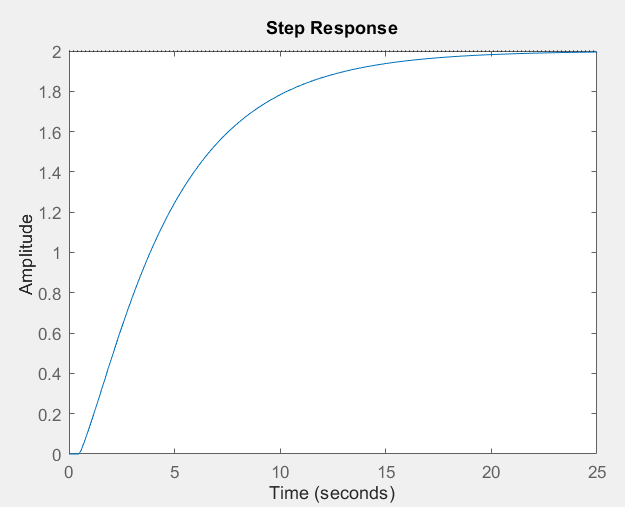

Y esta en lazo cerrado.

Con lo anterior se comienza a realizar la simulación usando Simulink. 

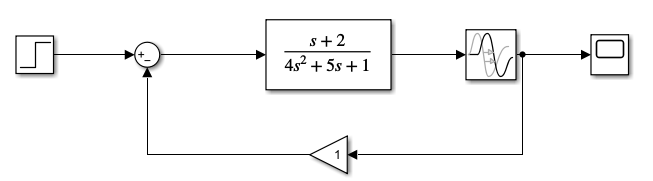

La salida de este sistema es el siguiente:

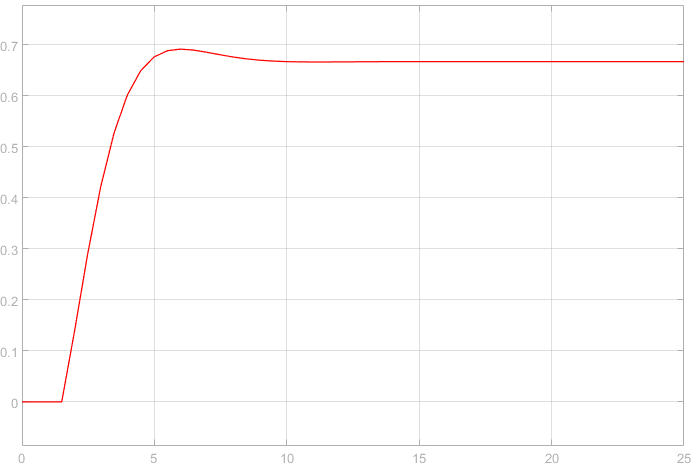

Luego se añade el controlador PID convencional, para ello se modela en simulink el siguiente diagrama y se utilizan las constantes reportadas:

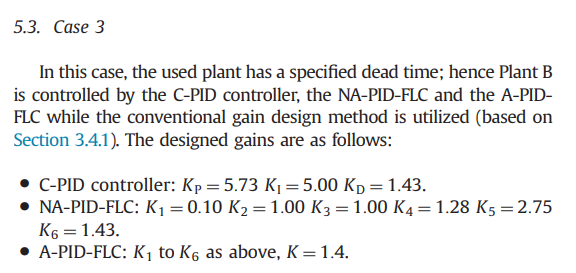

El diseño del controlador PID convencional es el siguiente:

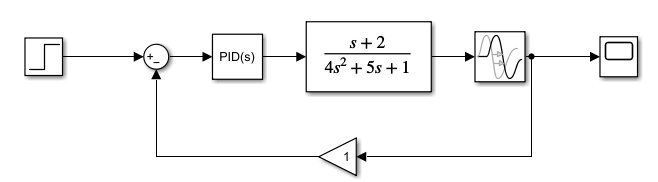

El diseño del controlado NA-PID-FLC es el siguiente:

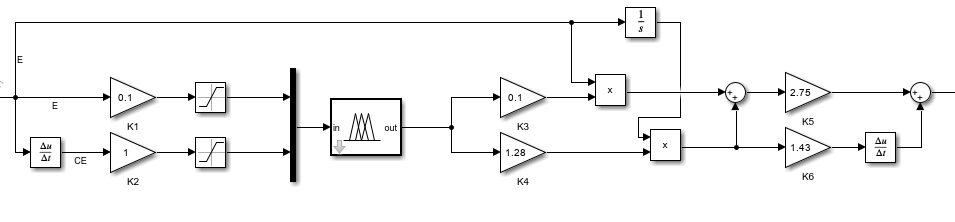

El diseño del controlador A-PID-FLC es el siguiente:

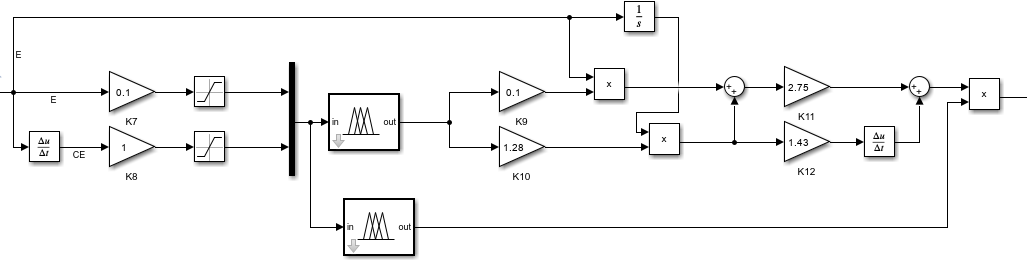

**5.** Reporte el resultado de las pruebas del control del numeral 4 por medio de la simulación de la planta con un modelo continuo y ante una señal de excitación tipo escalón.

**Respuesta:**

Se reporta la salida de cada variable en un tiempo t=100s.

Para el PID convencional:

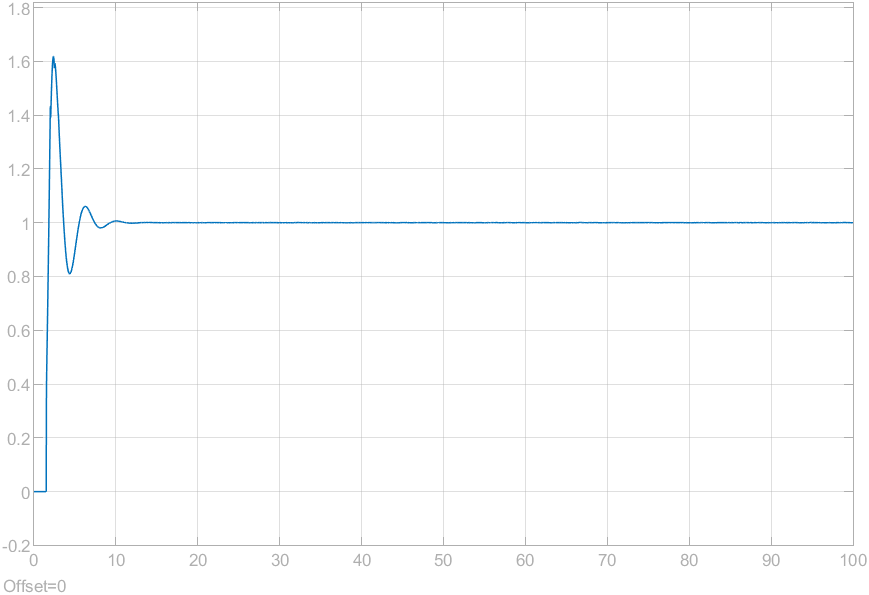

Para el controlador NA-PID-FLC:

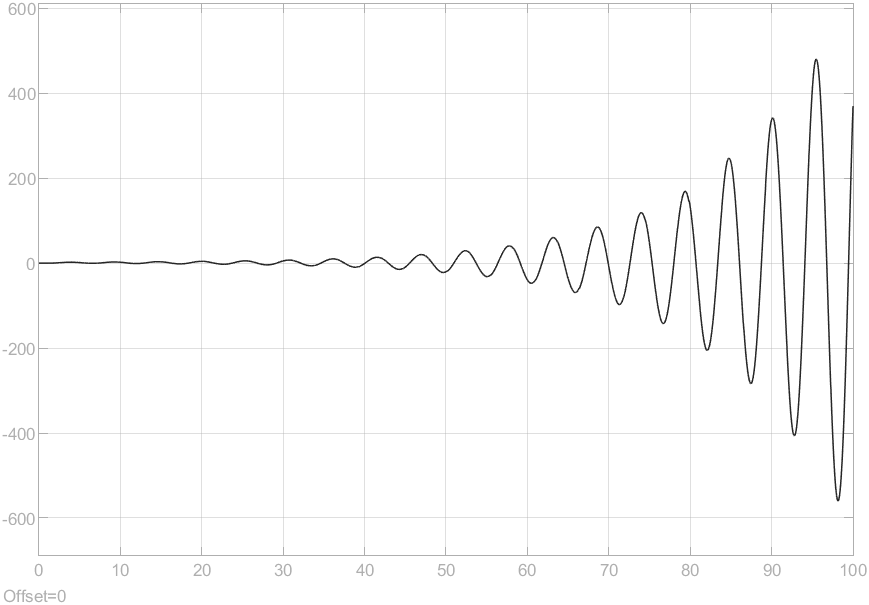

Para el controlador A-PID-FLC:

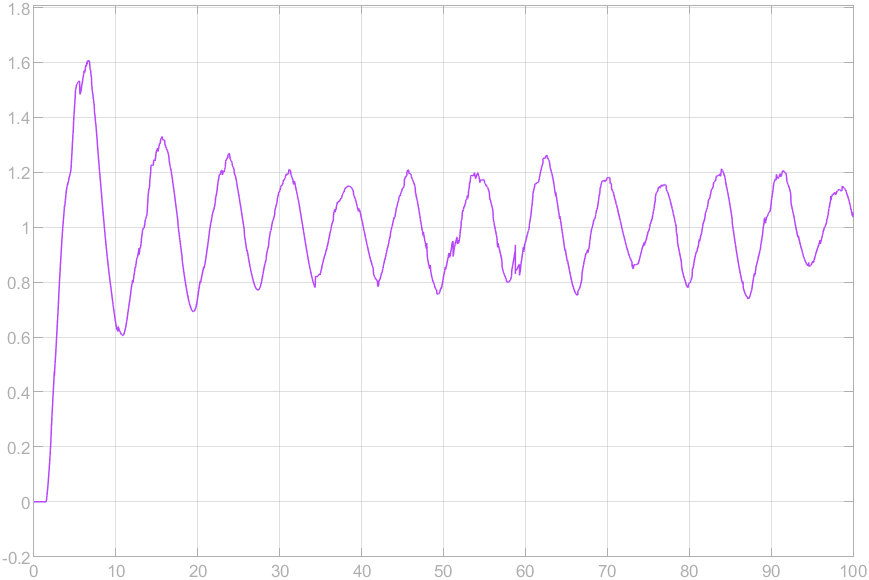

**6.** Reporte el resultado de las pruebas del control en la aplicación real, comparando con el desempeño de los controles PID de la anterior práctica y escoja de forma argumentada, la que demuestre un mejor resultado (acudir a la realización de tablas similares a los reportes pasados). 

**Respuesta:**

Para diseñar el controlador se crea la siguiente tabla de verdad:

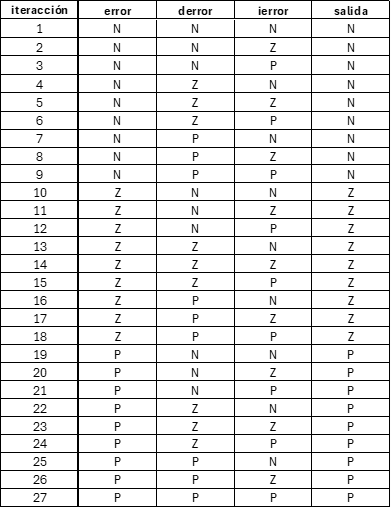

En esta se reconoce a los 3 tipos de errores que maneja un PID, y se les da 3 posibles estados. 

**P: **error Positivo

**Z: **Nada

**N:** error Negativo

Luego se diseña el controlador con fuzzy y se preseenta su estructura:

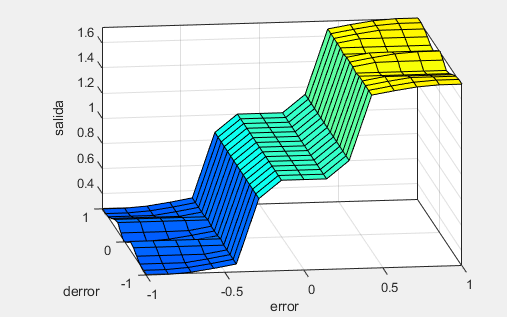

Utilizando simulink se diseña el experimento:

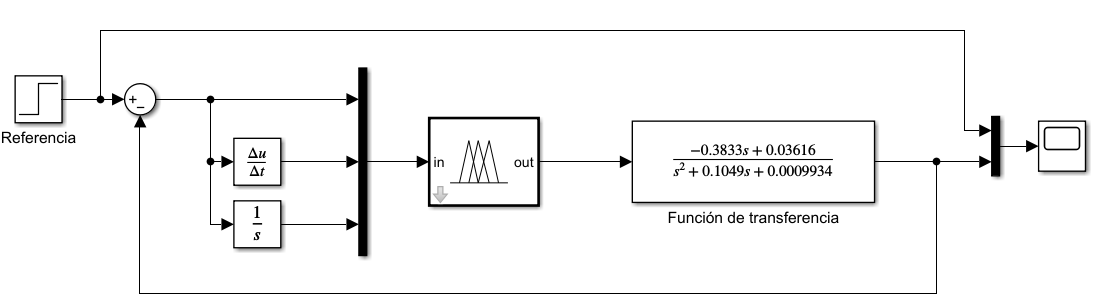

y la salida es:

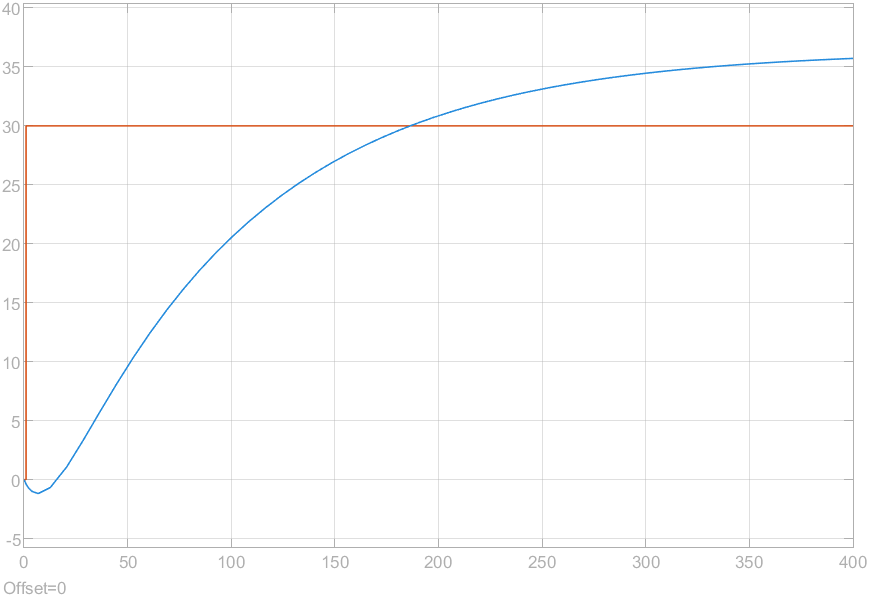

Finalmente se presenta una tabla comparativa